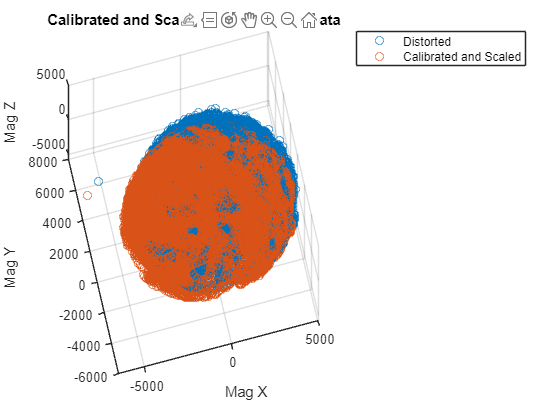

clear;
close all;

% Load magnetometer data from CSV file
data = readtable('./arastronaut/Arastronaut/matlab/magcalib/203smag_data.csv'); % Update with the actual file path

% Extract magnetometer columns
mag_ave = [data.Mag_X, data.Mag_Y, data.Mag_Z]; 

% Visualize the raw (distorted) magnetometer data
figure;
scatter3(mag_ave(:,1), mag_ave(:,2), mag_ave(:,3));
xlabel('Mag X'); ylabel('Mag Y'); zlabel('Mag Z');
title('Distorted Magnetometer Data (Before Calibration)');
grid on;
hold on;

% Find calibration coefficients using magcal
[A, b, expMFS] = magcal(mag_ave);

% Calculate scaling factors for each axis
x_scale = (max(mag_ave(:,1)) - min(mag_ave(:,1))) / 2;
y_scale = (max(mag_ave(:,2)) - min(mag_ave(:,2))) / 2;
z_scale = (max(mag_ave(:,3)) - min(mag_ave(:,3))) / 2;

% Combine scales into a vector
scale_factors = [x_scale, y_scale, z_scale];

% Apply the calibration and scaling to the raw data
xCorrected = (mag_ave - b) * A;

% Apply scaling factors to the corrected data
xCorrected_scaled = xCorrected ./ scale_factors;

% Visualize the calibrated and scaled magnetometer data
scatter3(xCorrected(:,1), xCorrected(:,2), xCorrected(:,3));
xlabel('Mag X'); ylabel('Mag Y'); zlabel('Mag Z');
title('Calibrated and Scaled Magnetometer Data');
legend('Distorted', 'Calibrated and Scaled');
grid on;


% Display calibration results
disp('Soft iron correction matrix (A):');

Soft iron correction matrix (A):


disp(A); % Soft iron correction matrix

    1.0515    0.0002   -0.0015
    0.0002    0.9327    0.0332
   -0.0015    0.0332    1.0208



disp('Hard iron correction bias (b):');

Hard iron correction bias (b):


disp(b); % Hard iron correction bias

  535.1414  872.0270 -730.9601



disp('Scaling factors:');

Scaling factors:


disp(['X scale: ', num2str(x_scale)]);

X scale: 5348.5


disp(['Y scale: ', num2str(y_scale)]);

Y scale: 5294.5


disp(['Z scale: ', num2str(z_scale)]);

Z scale: 4944.5


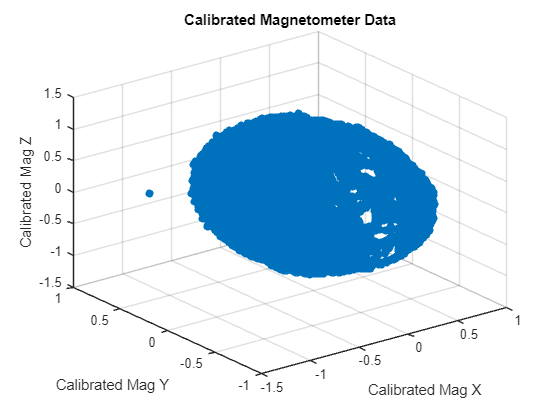


% Apply the calibration
calibratedMagData = (mag_ave - b) * A;

% Apply scaling factors to the corrected data
xCorrected_scaled = calibratedMagData ./ scale_factors;

% Visualize calibrated data
figure;
scatter3(xCorrected_scaled(:,1), xCorrected_scaled(:,2), xCorrected_scaled(:,3), 'filled');
xlabel('Calibrated Mag X'); ylabel('Calibrated Mag Y'); zlabel('Calibrated Mag Z');
title('Calibrated Magnetometer Data');
grid on;


% Save the calibrated data if needed
writetable(array2table(calibratedMagData, 'VariableNames', {'Mag_X', 'Mag_Y', 'Mag_Z'}), 'calibrated_magnetometer.csv');